# Comparison of Gaze Bias Parameters Across Species

## Load Data

NOTE: This graph, was created using the gramm toolbox. The toolbox is available at [this repository](https://github.com/piermorel/gramm). 

The mat file loaded below contains a table called *speciesParams, *which contains GLAM parameters for the four human datasets (reported in [this paper](https://www.nature.com/articles/s41562-019-0584-8), data obtained from [this repository](https://github.com/glamlab/gaze-bias-differences)) and the data from our two monkey subjects. 

The table contains the following variables for each subject (humans) /session (monkeys)):

- gamma: gaze-bias parameter for each subject

- s: noise parameter 

- tau: logistic tuning parameter

- v: velocity parameter

- dataset: categorical variable indicating which dataset the data came from. For the monkey subjects, this variable denotes which monkey the data came from. 

- species: cateogircal variable indicating whether the data came from one of the four human datasets. For the monkey subjects, this variable, too, denotes which monkey the data came from. 

clear;clc; close all
load GammaSpeciesComparison.mat

## Plot Distribution of Gaze-Bias Parameters

The colors in the graph indicate the species or, monkey. Dashed lines indicate the means for each dataset. These lines are replaced with inverted triangles above the distributions. 

% show means for each dataset
mean_dataset = grpstats(speciesParams,'dataset','mean','DataVars',{'gamma'})

mean_dataset = 6×3 table
                      dataset       GroupCount    mean_gamma
                    ____________    __________    __________

    MonkeyC         MonkeyC             29         0.035345 
    MonkeyK         MonkeyK             25         -0.20028 
    folke2016       folke2016           24        -0.017083 
    krajbich2010    krajbich2010        39          0.26282 
    krajbich2011    krajbich2011        30            0.179 
    tavares2017     tavares2017         25           0.0804 


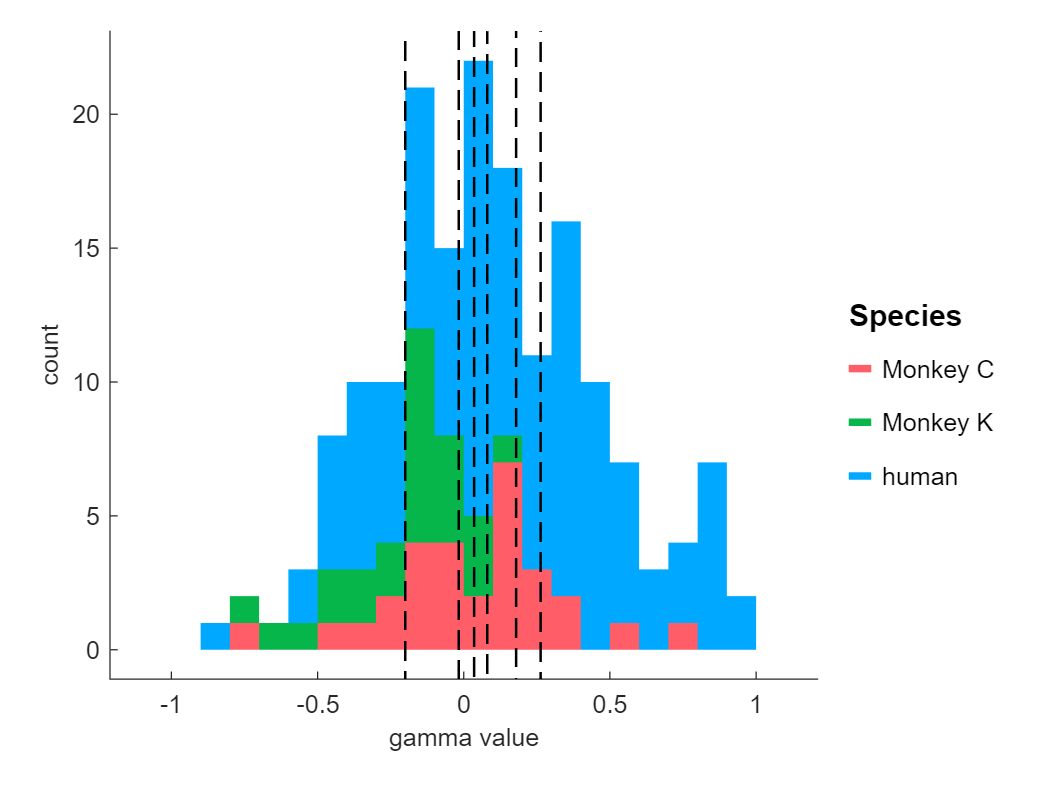

clf
g2 = gramm('x',speciesParams.gamma,'color',speciesParams.species);
g2.stat_bin('edges',[-1:0.1:1],'geom','stacked_bar','fill', 'all');
g2.geom_vline('xintercept',mean_dataset.mean_gamma);
g2.set_names("x",'gamma value','color','Species');
% g2.axe_property('PlotBoxAspectRatio',[1 1 1])
g2.draw();